**Ejercicio 1**

Ecuaciones del sistema


$$\dot{x}_1 = x_2 \\
\dot{x}_2 = x_1 +\epsilon x_1^2$$


Empezamos por construir las ecuaciones en simbólico para buscar los puntos de equilibrio.

syms x1 x2 e real
f(1,1) = x2

$$f = \left(\begin{array}{c} x_{2}\\ e\,{x_{1}}^{2}+x_{1} \end{array}\right)$$

f(2,1) = x1 + e*x1^2

$$f = \left(\begin{array}{c} x_{2}\\ e\,{x_{1}}^{2}+x_{1} \end{array}\right)$$

peq = solve(f)

peq = struct with fields:
    x1: [2×1 sym]
    x2: [2×1 sym]


peq = [peq.x1 peq.x2]'

$$peq = \left(\begin{array}{cc} 0 & -\frac{1}{e}\\ 0 & 0 \end{array}\right)$$

Es fácil ver que tenemos dos puntos de equilibrio uno es el $(0,0)$ que es independiente del parámetro $\epsilon$. El otro es $\left(-\frac{1}{\epsilon},0 \right)$. 

**Ejercicio 2**

Linealizamos, en torno a los puntos de equilibrio.

J = jacobian(f,[x1 x2])

$$J = \left(\begin{array}{cc} 0 & 1\\ 2\,e\,x_{1}+1 & 0 \end{array}\right)$$

Calculamos los autovalores del Jacobiano

Atval = eig(J)

$$Atval = \left(\begin{array}{c} -\sqrt{2\,e\,x_{1}+1}\\ \sqrt{2\,e\,x_{1}+1} \end{array}\right)$$

Sustituimos su valor en los dos puntos de equilibrio.

subs(Atval,x1,peq(1,:))

$$ans = \left(\begin{array}{cc} -1 & -\mathrm{i}\\ 1 & \mathrm{i} \end{array}\right)$$

 Obtemos un centro para $\left(\frac{1}{\epsilon},0 \right)$ y un punto de silla para (0,0) no podemos en general, concluir nada de la estabilidad del centro para el no lineal.

**Ejercicio 3**

Es evidente que para $\epsilon = 0$ este segundo punto de equlibrio se va a infinito o, lo que es lo mismo, desaparece y el sistema es inestable. Pero en las proximades de 0 el lío está servido, en el sentido de que altera la región en que el sistema es marginalmente estable. De hecho, en la medida que hacemos crecer $\epsilon$ vamos disminuyendo, más y más la region de estabilidad del centro, porque tiende a colapsar con el punto de silla situado en (0,0). El unico efecto que tiene cambiar de signo $\epsilon$ es cambiar a qué lado den origen se sitúa el punto de equilibrio correspondiente al centro.

**Ejercicio 4**

Dibujamos las soluciones para los casos particulares $\epsilon = 1$, $\epsilon = -1$y $\epsilon = 0$

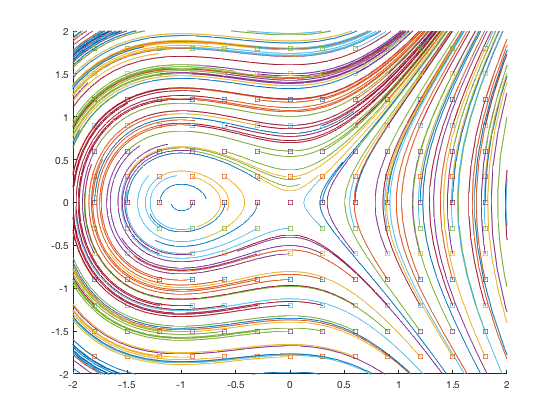

x1 = [-3:0.3:3];
x2 = [-3:0.3:3];
warning off
figure(1)
hold on
for i=1:length(x1)
    for j =1:length(x2)
       plot(x1(i),x2(j),'s')
       [t,x]=ode45(@(t,x)huevo(t,x,1),[0 3],[x1(i);x2(j)]);
       plot(x(:,1),x(:,2))
    end
end
axis([-2,2,-2,2])

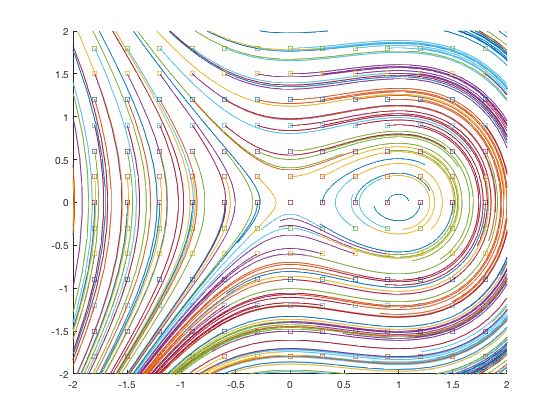

x1 = [-3:0.3:3];
x2 = [-3:0.3:3];
warning off
figure(2)
hold on
for i=1:length(x1)
    for j =1:length(x2)
       plot(x1(i),x2(j),'s')
       [t,x]=ode45(@(t,x)huevo(t,x,-1),[0 3],[x1(i);x2(j)]);
       plot(x(:,1),x(:,2))
    end
end
axis([-2,2,-2,2])

A partir de los gráficos podemos ver que la primera trayectoria inestable sería aquella que pasa exactamente por el punto de equilibrio $(0,0)$ cualquier punto que caiga dentro de ella seguirá una órbita estable en torno al punto de equilibrio $(-\frac{1}{\epsilon},0)$

Para el caso $\epsilon = 0$ solo se obtiene el punto de silla en el origen

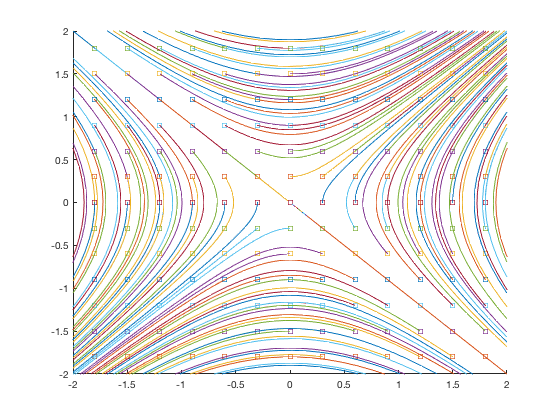

x1 = [-3:0.3:3];
x2 = [-3:0.3:3];
warning off
figure(3)
hold on
for i=1:length(x1)
    for j =1:length(x2)
       plot(x1(i),x2(j),'s')
       [t,x]=ode45(@(t,x)huevo(t,x,0),[0 3],[x1(i);x2(j)]);
       plot(x(:,1),x(:,2))
    end
end
axis([-2,2,-2,2])

function dx = huevo(t,x,e)
dx(1,1) = x(2,1);
dx(2,1) = x(1,1)+e*x(1,1)^2;
end